# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;

localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories; % adds rawDataFolder, latex_interpreter
rawDataFolder = "rawData";
clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 1

T = 1

macroItrMax = 100; % Max no. of permissible iterations for optimizing an area
noBatteries = false;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;
DER_percent = 10;
% Batt_percent = ~noBatteries*DER_percent;
Batt_percent = ~noBatteries * 10;
delta_t = 1.00; % one hour
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = true;

globalPVCoeff = 1.0;
[pvCoeffVals, lambdaVals, S_to_P_ratio_PV, ...
    S_to_P_ratio_Batt, costArray] = inputForecastData(rawDataFolder, T, globalPVCoeff);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numRelationships = numRelationships;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;

PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);

% y_allR_
sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;

simInfo = struct();
if copf
    simInfo.simName = "MPCOPF";
else
    simInfo.simName = "MPDOPF";
end
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
battstring = strcat('pv_', num2str(DER_percent), '_batt_', num2str(Batt_percent));
simInfo.battstring = battstring;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.S_to_P_ratio_PV = S_to_P_ratio_PV;
simInfo.S_to_P_ratio_Batt = S_to_P_ratio_Batt;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        

Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =      0
     0


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.144749e-04     1.770e-03     1.000e+00     3.881e-01     6.090e-02  
    2         831    4.043645e-04     1.202e-05     1.000e+00     6.602e-03     3.421e-03  
    3        1108    3.450973e-04     6.683e-05     1.000e+00     1.415e-02     2.828e-03  
    4        1385    2.598394e-04     3.953e-04     1.000e+00     3.459e-02     2.796e-03  
    5        1662    2.349031e-04     9.269e-05     1.000e+00     1.792e-02     2.286e-03  
    6        1939    1.974490e-04     2.188e-04     1.000e+00     3.032e-02     2.282e-03  
    7        2216    1.729317e-04     9.587e-05     1.000e+00     2.325e-02     2.016e-03  
    8        2493    1.537465e-04     6.284e-05     1.000e+00     1.857e-02     1.

Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT = 1.0609

S_chArs_1toT = 0

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     1.415e-02  
    1         268    5.951566e-04     1.195e-03     1.000e+00     2.741e-01     6.090e-02  
    2         402    5.323778e-04     1.510e-05     1.000e+00     1.060e-02     3.784e-03  
    3         537    3.113888e-04     5.053e-06     1.000e+00     3.923e-02     3.511e-03  
    4         672    2.202467e-04     4.872e-07     1.000e+00     4.019e-02     4.865e-03  
    5         807    1.930171e-04     3.361e-08     1.000e+00     1.808e-02     4.746e-03  
    6         942    1.751883e-04     6.966e-08     1.000e+00     1.619e-02     1.992e-03  
    7        1077    1.706618e-04     3.191e-09     1.000e+00     4.469e-03     8.231e-04  
    8        1212    1.674335e-04     3.063e-09     1.000e+00     4.477e-03     7.

Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    1.270122e-03     3.589e-03     1.000e+00     3.004e-01     6.090e-02  
    2         444    1.033141e-03     3.523e-05     1.000e+00     1.919e-02     5.802e-03  
    3         593    5.384093e-04     9.615e-06     1.000e+00     4.774e-02     6.774e-03  
    4         742    2.577703e-04     2.311e-06     1.000e+00     5.716e-02     8.611e-03  
    5         891    2.045852e-04     1.000e-06     1.000e+00     2.065e-02     6.535e-03  
    6        1040    1.728187e-04     1.000e-06     1.000e+00     2.205e-02     3.048e-03  
    7        1189    1.597581e-04     1.000e-06     1.000e+00     1.128e-02     2.648e-03  
    8        1338    1.535705e-04     2.946e-09     1.000e+00     5.257e-03     8.

Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.974e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    1.558864e-03     3.821e-02     1.000e+00     7.094e-01     1.974e-01  
    2        1182    1.938661e-03     7.658e-05     1.000e+00     8.052e-02     3.554e-02  
    3        1576    1.688805e-03     4.457e-05     1.000e+00     1.743e-02     6.288e-03  
    4        1970    1.418644e-03     3.943e-04     1.000e+00     4.688e-02     4.043e-03  
    5        2364    1.370704e-03     5.829e-05     1.000e+00     1.620e-02     6.497e-03  
    6        2758    1.201766e-03     6.163e-04     1.000e+00     5.135e-02     8.660e-03  
    7        3152    1.082720e-03     1.311e-03     1.000e+00     7.522e-02     3.915e-03  
    8        3546    1.073664e-03     9.654e-05     1.000e+00     2.167e-02     1.

Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.0739 + 0.0265i
   0.1081 + 0.0517i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     1.081e-01     1.000e+00     0.000e+00     2.401e-02  
    1         554    4.144750e-04     5.645e-02     1.000e+00     6.437e-01     2.128e-01  
    2         831    1.179790e-03     3.035e-06     1.000e+00     1.164e-01     5.383e-02  
    3        1108    1.157062e-03     1.038e-05     1.000e+00     5.734e-03     2.545e-03  
    4        1385    1.106871e-03     1.851e-04     1.000e+00     2.438e-02     2.113e-03  
    5        1662    1.098532e-03     2.396e-05     1.000e+00     9.467e-03     1.433e-03  
    6        1939    1.090808e-03     2.899e-05     1.000e+00     1.135e-02     8.609e-04  
    7        2216    1.087709e-03     5.624e-06     1.000e+00     5.768e-03     6.695e-04  
    8        2493    1.082589e-03     1.901e-05     1.000e+00     1.017e-02     9.

Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT = 1.0579

S_chArs_1toT = 0.1851 - 0.0798i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.851e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    5.951566e-04     4.309e-02     1.000e+00     5.951e-01     2.075e-01  
    2         402    1.368269e-03     1.486e-06     1.000e+00     1.058e-01     4.103e-02  
    3         536    1.282121e-03     2.241e-05     1.000e+00     1.231e-02     3.216e-03  
    4         670    1.131435e-03     3.231e-04     1.000e+00     4.743e-02     2.604e-03  
    5         804    1.126053e-03     1.394e-05     1.000e+00     1.114e-02     2.290e-03  
    6         938    1.118141e-03     1.631e-05     1.000e+00     1.157e-02     9.328e-04  
    7        1072    1.117611e-03     1.067e-06     1.000e+00     2.564e-03     4.188e-04  
    8        1206    1.117111e-03     5.529e-07     1.000e+00     1.741e-03     1.

Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT = 1.0568


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     5.676e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    1.270122e-03     3.589e-03     1.000e+00     2.843e-01     5.676e-02  
    2         444    1.033064e-03     3.533e-05     1.000e+00     1.922e-02     5.801e-03  
    3         593    5.240625e-04     1.096e-03     1.000e+00     4.732e-02     6.699e-03  
    4         742    2.699379e-04     1.670e-06     1.000e+00     5.475e-02     9.177e-03  
    5         891    2.060226e-04     1.000e-06     1.000e+00     2.337e-02     6.945e-03  
    6        1040    1.748945e-04     1.000e-06     1.000e+00     2.166e-02     3.213e-03  
    7        1189    1.621571e-04     2.145e-08     1.000e+00     1.088e-02     2.507e-03  
    8        1338    1.547342e-04     9.568e-09     1.000e+00     7.167e-03     1.

Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT = 1.0570


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.974e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    1.558864e-03     3.821e-02     1.000e+00     6.909e-01     1.974e-01  
    2        1182    1.941029e-03     7.650e-05     1.000e+00     8.079e-02     3.567e-02  
    3        1576    1.690924e-03     4.465e-05     1.000e+00     1.745e-02     6.292e-03  
    4        1970    1.420802e-03     3.943e-04     1.000e+00     4.688e-02     4.041e-03  
    5        2364    1.372952e-03     5.819e-05     1.000e+00     1.618e-02     6.490e-03  
    6        2758    1.204106e-03     6.177e-04     1.000e+00     5.141e-02     8.646e-03  
    7        3152    1.085741e-03     1.300e-03     1.000e+00     7.492e-02     3.925e-03  
    8        3546    1.076645e-03     9.649e-05     1.000e+00     2.166e-02     1.

Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.2395 - 0.0021i
   0.1080 + 0.0517i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     2.395e-01     1.000e+00     0.000e+00     2.401e-02  
    1         555    2.040236e-04     7.307e-02     7.000e-01     6.691e-01     2.649e-01  
    2         832    2.089560e-03     1.157e-02     1.000e+00     4.100e-01     1.337e-01  
    3        1109    2.218296e-03     4.359e-06     1.000e+00     2.596e-02     2.767e-03  
    4        1386    2.208718e-03     3.602e-06     1.000e+00     3.912e-03     1.392e-03  
    5        1663    2.187563e-03     7.778e-05     1.000e+00     1.787e-02     8.948e-04  
    6        1940    2.186977e-03     3.143e-06     1.000e+00     3.775e-03     4.199e-04  
    7        2217    2.186320e-03     1.529e-06     1.000e+00     2.900e-03     2.625e-04  
    8        2494    2.186123e-03     1.955e-07     1.000e+00     1.164e-03     2.

Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1.0503

S_chArs_1toT = 0.1850 - 0.0798i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.850e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    5.951566e-04     4.303e-02     1.000e+00     5.827e-01     2.074e-01  
    2         402    1.372166e-03     1.672e-06     1.000e+00     1.065e-01     4.128e-02  
    3         536    1.284605e-03     2.353e-05     1.000e+00     1.258e-02     3.285e-03  
    4         670    1.136438e-03     3.203e-04     1.000e+00     4.716e-02     2.526e-03  
    5         804    1.131261e-03     1.350e-05     1.000e+00     1.104e-02     2.266e-03  
    6         938    1.123690e-03     1.536e-05     1.000e+00     1.127e-02     8.780e-04  
    7        1072    1.123195e-03     1.052e-06     1.000e+00     2.540e-03     4.011e-04  
    8        1206    1.122728e-03     5.202e-07     1.000e+00     1.722e-03     1.

Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1.0459


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     4.590e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    1.270122e-03     3.589e-03     1.000e+00     2.439e-01     5.144e-02  
    2         444    1.032625e-03     3.568e-05     1.000e+00     1.932e-02     5.798e-03  
    3         593    5.393153e-04     9.788e-06     1.000e+00     4.767e-02     6.738e-03  
    4         742    2.567648e-04     2.622e-06     1.000e+00     5.848e-02     8.678e-03  
    5         891    2.067870e-04     1.000e-06     1.000e+00     1.940e-02     6.445e-03  
    6        1040    1.747376e-04     1.000e-06     1.000e+00     2.218e-02     2.884e-03  
    7        1189    1.623049e-04     1.644e-07     1.000e+00     1.088e-02     2.568e-03  
    8        1338    1.557032e-04     3.252e-09     1.000e+00     5.998e-03     8.

Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1.0514


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.974e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    1.558864e-03     3.821e-02     1.000e+00     6.660e-01     1.974e-01  
    2        1182    1.944470e-03     7.638e-05     1.000e+00     8.117e-02     3.585e-02  
    3        1576    1.693994e-03     4.477e-05     1.000e+00     1.747e-02     6.296e-03  
    4        1970    1.423939e-03     3.942e-04     1.000e+00     4.687e-02     4.037e-03  
    5        2364    1.376218e-03     5.804e-05     1.000e+00     1.616e-02     6.480e-03  
    6        2758    1.207419e-03     6.205e-04     1.000e+00     5.153e-02     8.628e-03  
    7        3152    1.089997e-03     1.289e-03     1.000e+00     7.459e-02     3.941e-03  
    8        3546    1.080922e-03     9.581e-05     1.000e+00     2.159e-02     1.

Macro-iteration 4: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.2310 - 0.0007i
   0.1080 + 0.0517i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     2.310e-01     1.000e+00     0.000e+00     2.401e-02  
    1         555    2.040236e-04     7.004e-02     7.000e-01     6.564e-01     2.589e-01  
    2         832    2.024436e-03     1.109e-02     1.000e+00     3.974e-01     1.281e-01  
    3        1109    2.147253e-03     4.531e-06     1.000e+00     2.493e-02     2.764e-03  
    4        1386    2.137360e-03     3.788e-06     1.000e+00     3.996e-03     1.411e-03  
    5        1663    2.115515e-03     8.167e-05     1.000e+00     1.821e-02     9.011e-04  
    6        1940    2.114845e-03     3.487e-06     1.000e+00     3.954e-03     4.360e-04  
    7        2217    2.114140e-03     1.649e-06     1.000e+00     3.002e-03     2.658e-04  
    8        2494    2.113931e-03     2.104e-07     1.000e+00     1.199e-03     2.

Macro-iteration 4: Running OPF for Area 2.


v_parAr_1toT = 1.0482

S_chArs_1toT = 0.1849 - 0.0798i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.849e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    5.951566e-04     4.298e-02     1.000e+00     5.793e-01     2.073e-01  
    2         402    1.372715e-03     1.723e-06     1.000e+00     1.066e-01     4.131e-02  
    3         536    1.284750e-03     2.385e-05     1.000e+00     1.266e-02     3.304e-03  
    4         670    1.137249e-03     3.195e-04     1.000e+00     4.709e-02     2.505e-03  
    5         804    1.132122e-03     1.339e-05     1.000e+00     1.102e-02     2.260e-03  
    6         938    1.124637e-03     1.510e-05     1.000e+00     1.119e-02     8.639e-04  
    7        1072    1.124150e-03     1.054e-06     1.000e+00     2.541e-03     3.963e-04  
    8        1206    1.123692e-03     5.110e-07     1.000e+00     1.717e-03     1.

Macro-iteration 4: Running OPF for Area 3.


v_parAr_1toT = 1.0439


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     4.392e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    1.270122e-03     3.589e-03     1.000e+00     2.368e-01     5.144e-02  
    2         444    1.032459e-03     3.580e-05     1.000e+00     1.935e-02     5.799e-03  
    3         593    5.392576e-04     9.710e-06     1.000e+00     4.770e-02     6.727e-03  
    4         742    2.568789e-04     2.751e-06     1.000e+00     5.884e-02     8.676e-03  
    5         891    2.075896e-04     1.000e-06     1.000e+00     1.906e-02     6.445e-03  
    6        1040    1.753191e-04     1.000e-06     1.000e+00     2.219e-02     2.838e-03  
    7        1189    1.630209e-04     3.172e-08     1.000e+00     1.076e-02     2.539e-03  
    8        1338    1.564179e-04     3.323e-09     1.000e+00     6.062e-03     8.

Macro-iteration 4: Running OPF for Area 4.


v_parAr_1toT = 1.0442


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.974e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    1.558864e-03     3.821e-02     1.000e+00     6.359e-01     1.973e-01  
    2        1182    1.949132e-03     7.622e-05     1.000e+00     8.168e-02     3.610e-02  
    3        1576    1.698141e-03     4.493e-05     1.000e+00     1.750e-02     6.303e-03  
    4        1970    1.428183e-03     3.942e-04     1.000e+00     4.687e-02     4.032e-03  
    5        2364    1.380614e-03     5.789e-05     1.000e+00     1.614e-02     6.468e-03  
    6        2758    1.211979e-03     6.232e-04     1.000e+00     5.164e-02     8.608e-03  
    7        3152    1.095705e-03     1.274e-03     1.000e+00     7.417e-02     3.972e-03  
    8        3546    1.086486e-03     9.886e-05     1.000e+00     2.192e-02     1.

Macro-iteration 5: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.2391 - 0.0021i
   0.1079 + 0.0517i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         277    0.000000e+00     2.391e-01     1.000e+00     0.000e+00     2.401e-02  
    1         555    2.040236e-04     7.289e-02     7.000e-01     6.683e-01     2.645e-01  
    2         832    2.085337e-03     1.154e-02     1.000e+00     4.093e-01     1.333e-01  
    3        1109    2.213688e-03     4.369e-06     1.000e+00     2.590e-02     2.767e-03  
    4        1386    2.204092e-03     3.612e-06     1.000e+00     3.917e-03     1.393e-03  
    5        1663    2.182897e-03     7.800e-05     1.000e+00     1.789e-02     8.952e-04  
    6        1940    2.182306e-03     3.164e-06     1.000e+00     3.786e-03     4.208e-04  
    7        2217    2.181646e-03     1.536e-06     1.000e+00     2.906e-03     2.627e-04  
    8        2494    2.181449e-03     1.962e-07     1.000e+00     1.166e-03     2.

Macro-iteration 5: Running OPF for Area 2.


v_parAr_1toT = 1.0482

S_chArs_1toT = 0.1847 - 0.0798i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         134    0.000000e+00     1.847e-01     1.000e+00     0.000e+00     1.415e-02  
    1         268    5.951566e-04     4.290e-02     1.000e+00     5.789e-01     2.071e-01  
    2         402    1.371234e-03     1.714e-06     1.000e+00     1.064e-01     4.123e-02  
    3         536    1.283231e-03     2.386e-05     1.000e+00     1.266e-02     3.305e-03  
    4         670    1.135621e-03     3.198e-04     1.000e+00     4.711e-02     2.507e-03  
    5         804    1.130480e-03     1.341e-05     1.000e+00     1.103e-02     2.262e-03  
    6         938    1.122981e-03     1.514e-05     1.000e+00     1.120e-02     8.655e-04  
    7        1072    1.122490e-03     1.061e-06     1.000e+00     2.550e-03     3.972e-04  
    8        1206    1.122031e-03     5.122e-07     1.000e+00     1.719e-03     1.

Macro-iteration 5: Running OPF for Area 3.


v_parAr_1toT = 1.0439


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         148    0.000000e+00     4.394e-02     1.000e+00     0.000e+00     2.183e-02  
    1         296    1.270122e-03     3.589e-03     1.000e+00     2.369e-01     5.144e-02  
    2         444    1.032462e-03     3.580e-05     1.000e+00     1.935e-02     5.799e-03  
    3         593    5.392573e-04     9.709e-06     1.000e+00     4.770e-02     6.727e-03  
    4         742    2.568777e-04     2.749e-06     1.000e+00     5.883e-02     8.676e-03  
    5         891    2.075796e-04     1.000e-06     1.000e+00     1.907e-02     6.445e-03  
    6        1040    1.753117e-04     1.000e-06     1.000e+00     2.219e-02     2.838e-03  
    7        1189    1.630117e-04     3.172e-08     1.000e+00     1.077e-02     2.540e-03  
    8        1338    1.564084e-04     3.322e-09     1.000e+00     6.062e-03     8.

Macro-iteration 5: Running OPF for Area 4.


v_parAr_1toT = 1.0418


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         394    0.000000e+00     1.974e-01     1.000e+00     0.000e+00     3.055e-02  
    1         788    1.558864e-03     3.821e-02     1.000e+00     6.266e-01     1.973e-01  
    2        1182    1.950724e-03     7.617e-05     1.000e+00     8.185e-02     3.618e-02  
    3        1576    1.699554e-03     4.499e-05     1.000e+00     1.751e-02     6.305e-03  
    4        1970    1.429630e-03     3.942e-04     1.000e+00     4.686e-02     4.031e-03  
    5        2364    1.382110e-03     5.784e-05     1.000e+00     1.613e-02     6.465e-03  
    6        2758    1.213508e-03     6.242e-04     1.000e+00     5.169e-02     8.602e-03  
    7        3152    1.097681e-03     1.266e-03     1.000e+00     7.396e-02     3.980e-03  
    8        3546    1.088370e-03     1.001e-04     1.000e+00     2.205e-02     1.

        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)

xVals_Area_1toT =     0.0980
    0.0980
    0.0028
    0.0141
    0.0058
    0.0083
    0.0057
    0.0751
    0.0725
    0.0134


xVals_Area_1toT =     0.0739
    0.0739
    0.0678
    0.0618
    0.0054
    0.0027
    0.0564
    0.0050
    0.0025
    0.0513


xVals_Area_1toT =     0.1081
    0.1081
    0.0112
    0.0058
    0.0054
    0.0027
    0.0908
    0.0026
    0.0882
    0.0055


xVals_Area_1toT =     0.1851
    0.1851
    0.1851
    0.0156
    0.0131
    0.0076
    0.0054
    0.1136
    0.0157
    0.0103


xVals_Area_1toT =     0.2489
    0.2489
    0.0023
    0.0126
    0.0053
    0.0073
    0.0052
    0.2283
    0.2264
    0.0100


xVals_Area_1toT =     0.2395
    0.2395
    0.2338
    0.2286
    0.0034
    0.0017
    0.2252
    0.0020
    0.0010
    0.2230


xVals_Area_1toT =     0.1080
    0.1080
    0.0112
    0.0058
    0.0054
    0.0027
    0.0908
    0.0026
    0.0882
    0.0055


xVals_Area_1toT =     0.1850
    0.1850
    0.1850
    0.0156
    0.0131
    0.0076
    0.0054
    0.1135
    0.0156
    0.0103


xVals_Area_1toT =     0.3962
    0.3962
    0.0018
    0.0112
    0.0048
    0.0063
    0.0047
    0.3777
    0.3765
    0.0073


xVals_Area_1toT =     0.2392
    0.2392
    0.2335
    0.2283
    0.0034
    0.0017
    0.2249
    0.0020
    0.0010
    0.2228


xVals_Area_1toT =     0.1079
    0.1079
    0.0112
    0.0058
    0.0054
    0.0027
    0.0907
    0.0026
    0.0881
    0.0055


xVals_Area_1toT =     0.1848
    0.1848
    0.1848
    0.0156
    0.0131
    0.0076
    0.0054
    0.1134
    0.0156
    0.0103


xVals_Area_1toT =     0.3881
    0.3881
    0.0018
    0.0112
    0.0048
    0.0064
    0.0047
    0.3695
    0.3682
    0.0074


xVals_Area_1toT =     0.2390
    0.2390
    0.2333
    0.2282
    0.0033
    0.0017
    0.2247
    0.0019
    0.0010
    0.2226


xVals_Area_1toT =     0.1079
    0.1079
    0.0112
    0.0058
    0.0054
    0.0027
    0.0907
    0.0026
    0.0881
    0.0055


xVals_Area_1toT =     0.1846
    0.1846
    0.1846
    0.0156
    0.0131
    0.0076
    0.0053
    0.1133
    0.0156
    0.0103


xVals_Area_1toT =     0.3958
    0.3958
    0.0018
    0.0112
    0.0048
    0.0063
    0.0047
    0.3772
    0.3760
    0.0073


xVals_Area_1toT =     0.2388
    0.2388
    0.2331
    0.2280
    0.0033
    0.0017
    0.2246
    0.0020
    0.0010
    0.2224


xVals_Area_1toT =     0.1079
    0.1079
    0.0112
    0.0058
    0.0054
    0.0027
    0.0907
    0.0026
    0.0881
    0.0055


xVals_Area_1toT =     0.1845
    0.1845
    0.1845
    0.0156
    0.0131
    0.0076
    0.0053
    0.1132
    0.0156
    0.0103


        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij); %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij); %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj); %N_Areax1
        V_Area_1toT = sqrt(vAll_Area_1toT);
        qD_Area_1toT = xVals_Area(areaInfo.indices_qDj);
        qD_AreaFull_1toT = sparseArrayFromDense(qD_Area_1toT, N_Area, areaInfo.busesWithDERs_Area);
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        PSubs_allT_vs_macroItr(macroItr+1) = PSubs_allT_vs_macroItr(macroItr+1) + areaInfo.PSubs_allT;
        PSubs_1toT_vs_macroItr(1:T, macroItr+1) = PSubs_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubs_1toT;
        PSubsCost_allT_vs_macroItr(macroItr+1) = PSubsCost_allT_vs_macroItr(macroItr+1) + areaInfo.PSubsCost_allT;
        PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubsCost_1toT;

        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr+1, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 1.0884e-22 - 5.4889e-23i

S12_intoChild_1toT = 0.0739 + 0.0265i

delta_S12_1toT = -0.0739 - 0.0265i

delta_v_1toT = -0.0030

Macro-iteration 1: Current Biggest Residual is 7.847524e-02 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = -6.0727e-26 + 2.1077e-22i

S12_intoChild_1toT = 0.1081 + 0.0517i

delta_S12_1toT = -0.1081 - 0.0517i

delta_v_1toT = -0.0041

Macro-iteration 1: Current Biggest Residual is 1.198103e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = -2.7622e-23 - 2.1402e-23i

S12_intoChild_1toT = 0.1851 - 0.0798i

delta_S12_1toT = -0.1851 + 0.0798i

delta_v_1toT = -0.0039

Macro-iteration 1: Current Biggest Residual is 2.016189e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0579
    1.0609
    1.0609


    1.0579



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0739 + 0.0265i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


   0.0739 + 0.0265i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0579
    1.0568
    1.0609


    1.0568



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0739 + 0.0265i
   0.1081 + 0.0517i
   0.0000 + 0.0000i


   0.1081 + 0.0517i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0579
    1.0568
    1.0570


    1.0570



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0739 + 0.0265i
   0.1081 + 0.0517i
   0.1851 - 0.0798i


   0.1851 - 0.0798i



Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.0739 + 0.0265i

S12_intoChild_1toT = 0.2395 - 0.0021i

delta_S12_1toT = -0.1656 + 0.0286i

delta_v_1toT = -0.0076

Macro-iteration 2: Current Biggest Residual is 1.680874e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1081 + 0.0517i

S12_intoChild_1toT = 0.1080 + 0.0517i

delta_S12_1toT = 3.9135e-05 - 7.3017e-07i

delta_v_1toT = -0.0109

Macro-iteration 2: Current Biggest Residual is 1.086531e-02 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1851 - 0.0798i

S12_intoChild_1toT = 0.1850 - 0.0798i

delta_S12_1toT = 1.1889e-04 - 9.2977e-07i

delta_v_1toT = -0.0055

Macro-iteration 2: Current Biggest Residual is 5.537457e-03 at index 2.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0568
    1.0570


    1.0503



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.2395 - 0.0021i
   0.1081 + 0.0517i
   0.1851 - 0.0798i


   0.2395 - 0.0021i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0459
    1.0570


    1.0459



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.2395 - 0.0021i
   0.1080 + 0.0517i
   0.1851 - 0.0798i


   0.1080 + 0.0517i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0503
    1.0459
    1.0514


    1.0514



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.2395 - 0.0021i
   0.1080 + 0.0517i
   0.1850 - 0.0798i


   0.1850 - 0.0798i



Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.2395 - 0.0021i

S12_intoChild_1toT = 0.2392 - 0.0021i

delta_S12_1toT = 2.9747e-04 + 2.1018e-05i

delta_v_1toT = -0.0022

Macro-iteration 3: Current Biggest Residual is 2.249349e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1080 + 0.0517i

S12_intoChild_1toT = 0.1079 + 0.0517i

delta_S12_1toT = 1.0476e-04 - 2.3323e-06i

delta_v_1toT = -0.0021

Macro-iteration 3: Current Biggest Residual is 2.083805e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1850 - 0.0798i

S12_intoChild_1toT = 0.1848 - 0.0798i

delta_S12_1toT = 1.6750e-04 - 2.8171e-06i

delta_v_1toT = -0.0076

Macro-iteration 3: Current Biggest Residual is 7.615419e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0459
    1.0514


***Macro-iteration 3 Communication Power:****


   0.2310 - 0.0007i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0439
    1.0514


***Macro-iteration 3 Communication Power:****


   0.1080 + 0.0517i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0439
    1.0442


***Macro-iteration 3 Communication Power:****


   0.1849 - 0.0798i



Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.2310 - 0.0007i

S12_intoChild_1toT = 0.2390 - 0.0021i

delta_S12_1toT = -0.0080 + 0.0014i

delta_v_1toT = 2.0374e-05

Macro-iteration 4: Current Biggest Residual is 8.166552e-03 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1080 + 0.0517i

S12_intoChild_1toT = 0.1079 + 0.0517i

delta_S12_1toT = 5.3600e-05 - 1.0543e-06i

delta_v_1toT = 2.9536e-05

Macro-iteration 4: Current Biggest Residual is 5.361072e-05 at index 1.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1849 - 0.0798i

S12_intoChild_1toT = 0.1846 - 0.0798i

delta_S12_1toT = 2.8064e-04 - 1.5663e-06i

delta_v_1toT = -0.0025

Macro-iteration 4: Current Biggest Residual is 2.511966e-03 at index 2.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0439
    1.0442


***Macro-iteration 4 Communication Power:****


   0.2391 - 0.0021i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0439
    1.0442


***Macro-iteration 4 Communication Power:****


   0.1079 + 0.0517i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0482
    1.0439
    1.0418


***Macro-iteration 4 Communication Power:****


   0.1847 - 0.0798i



Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.2391 - 0.0021i

S12_intoChild_1toT = 0.2388 - 0.0021i

delta_S12_1toT = 2.4640e-04 + 2.8503e-06i

delta_v_1toT = -1.1333e-04

Macro-iteration 5: Current Biggest Residual is 2.464199e-04 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1079 + 0.0517i

S12_intoChild_1toT = 0.1079 + 0.0517i

delta_S12_1toT = 1.1202e-05 - 2.7273e-08i

delta_v_1toT = -1.1239e-04

Macro-iteration 5: Current Biggest Residual is 1.123909e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.1847 - 0.0798i

S12_intoChild_1toT = 0.1845 - 0.0798i

delta_S12_1toT = 1.5157e-04 - 3.2399e-06i

delta_v_1toT = -8.6060e-05

Macro-iteration 5: Current Biggest Residual is 1.516010e-04 at index 1.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 Converged in 5 macro-iterations!


sysInfo = truncateSysInfo(sysInfo, macroItr);

saveSCDPlots = true

saveSCDPlots = logical
   1


if Batt_percent > 0 && saveSCDPlots
    for Area = 1:numAreas
        areaInfo = sysInfo.Area{Area};
        xValsArea_1toT = areaInfo.xvals;
        checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
    end
end

Checking for SCD for Area 1
Checking for SCD for Area 2
Checking for SCD for Area 3
Checking for SCD for Area 4


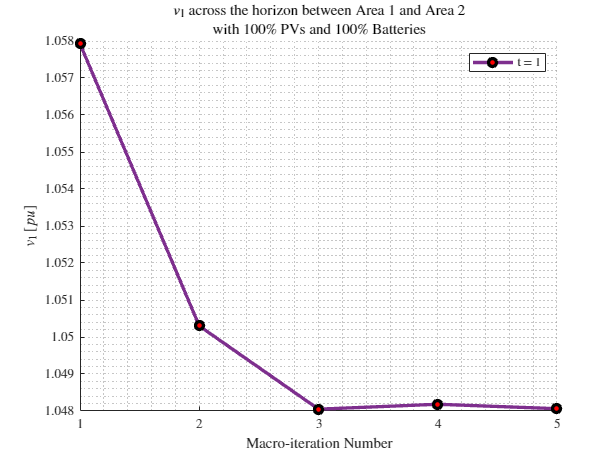

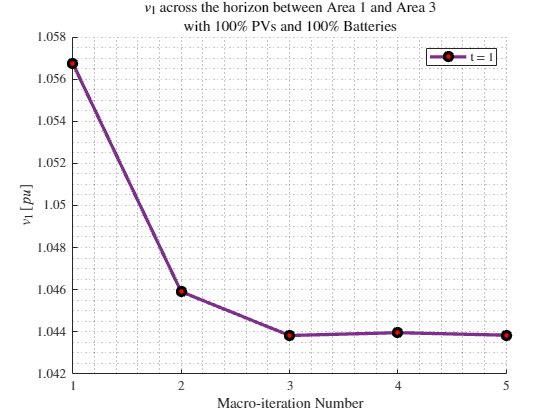

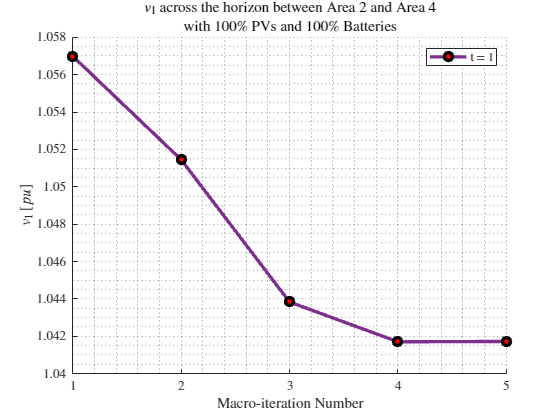

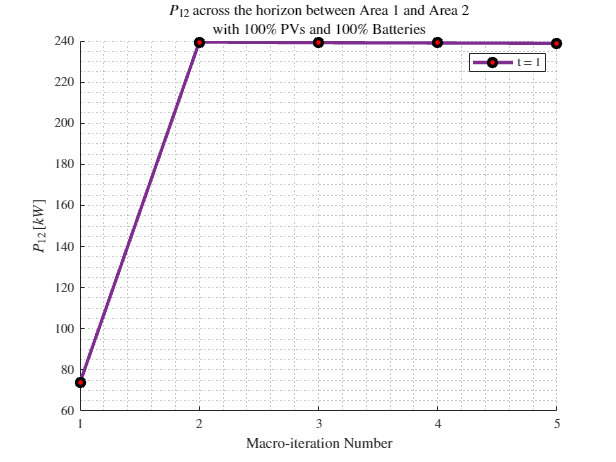

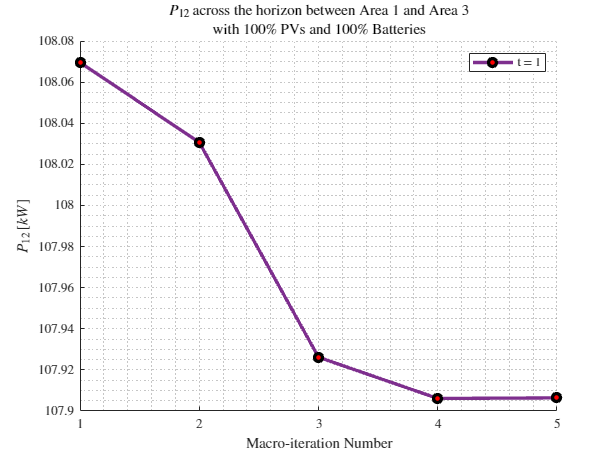

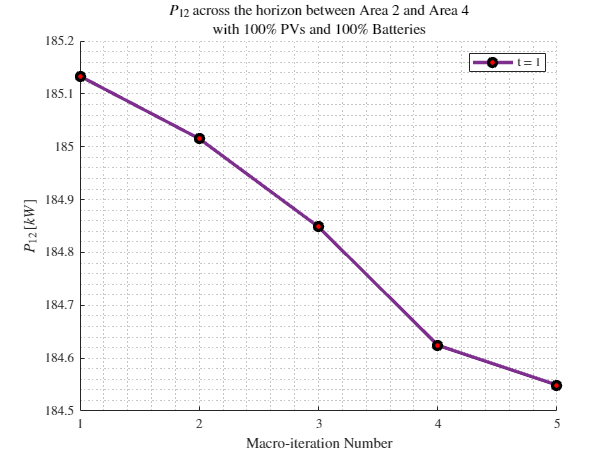

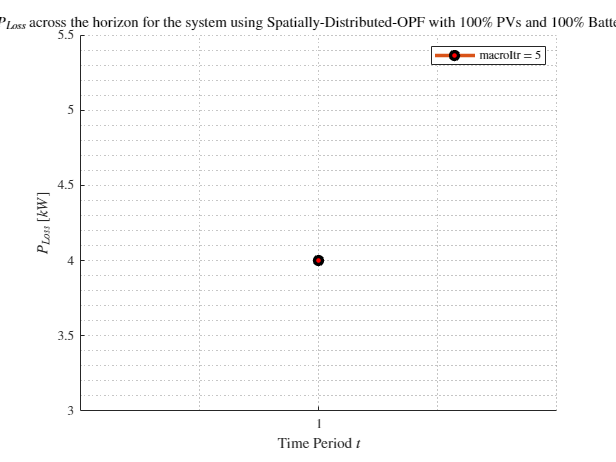

PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
results.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;

results.PLoss_allT = PLoss_allT_vs_macroItr(macroItr+1);
results.PLoss_1toT = PLoss_1toT_vs_macroItr(1:T, macroItr+1);
results.PSubs_allT = PSubs_allT_vs_macroItr(macroItr+1);
results.PSubs_1toT = PSubs_1toT_vs_macroItr(1:T, macroItr+1);
results.PSubsCost_allT = PSubsCost_allT_vs_macroItr(macroItr+1);
results.PSubsCost_1toT = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1);

% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 262.4103

    
lineLoss_kW_allT = 0;
lineLoss_kW_1toT = zeros(T, 1);

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW_1toT = areaInfo.PLoss_1toT * kVA_B;
    lineLoss_kW_1toT = lineLoss_kW_1toT + lineLoss_Area_kW_1toT;
    lineLoss_Area_kW_allT = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW_allT = lineLoss_kW_allT + lineLoss_Area_kW_allT;
end
area1Info = sysInfo.Area{1};
genCost_dollars_1toT = area1Info.PSubsCost_1toT * 1e-2;

% substationPower_kW_1toT = area1Info.P_Area_1toT(1, :)*kVA_B;
substationPower_kW_1toT = sysInfo.PSubs_1toT_vs_macroItr(1:T, macroItr+1) * kVA_B;


maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

vald = struct();
vald.res = results;

if copf
    vald.loadShape = lambdaVals;

    vald.loadShapePV = pvCoeffVals;
    vald.busesWithDERs_Area = area1Info.busesWithDERs_Area;
    vald.Pmpp_AreaFull = area1Info.Pmpp_Area;
    vald.Pmpp_Area = area1Info.Pmpp_Area(vald.busesWithDERs_Area);
    vald.Sder_AreaFull = area1Info.S_der_Area;

    vald.V_copf = V_Area_1toT;
    vald.pL_AreaFull_1toT = area1Info.P_L_Area_1toT;
    pLTotal_kW_1toT = sum(vald.pL_AreaFull_1toT)*kVA_B;
    vald.qL_AreaFull_1toT = area1Info.Q_L_Area_1toT;
    qLTotal_kVAr_1toT = sum(vald.qL_AreaFull_1toT)*kVA_B;
    
    % vald.pD_AreaFull_1toT = area1Info.P_der_Area_1toT;
    pD_AreaFull_1toT = area1Info.P_der_Area_1toT;
    vald.pD_AreaFull_1toT = pD_AreaFull_1toT;
    pDTotal_kW_1toT = sum(vald.pD_AreaFull_1toT)*kVA_B;
    vald.qD_AreaFull_1toT = qD_AreaFull_1toT;
    busesWithDERs_Area = area1Info.busesWithDERs_Area;
    qD_onlyBusesWithDERs_1toT = qD_AreaFull_1toT(busesWithDERs_Area, 1:T);
    pD_onlyBusesWithDERs_1toT = pD_AreaFull_1toT(busesWithDERs_Area, 1:T);
    vald.pD_Area_1toT = pD_onlyBusesWithDERs_1toT;
    vald.qD_Area_1toT = qD_onlyBusesWithDERs_1toT;
    Sder_AreaFull = area1Info.S_der_Area;
    Sder_onlyBusesWithDERs = Sder_AreaFull(busesWithDERs_Area);
    vald.Sder_Area = Sder_onlyBusesWithDERs;
    qDTotal_kVAr_1toT = sum(vald.qD_AreaFull_1toT)*kVA_B;

    vald.qC_AreaFull = area1Info.Q_C_Area;
    qCTotal_kVAr_1toT = repmat(sum(vald.qC_AreaFull), 1, T)*kVA_B;

    vald.busesWithBatt_Area = area1Info.busesWithBatts_Area;
    vald.S_battMax_Area = area1Info.S_onlyBattBusesMax_Area; % Actually this has 128 elements, so is 'Full'
    vald.Pd_Area_1toT = area1Info.Pd_Area_1toT;
    vald.P_battMax_Area = area1Info.P_onlyBattBusesMax_Area;
    PdTotal_kW_1toT = sum(vald.Pd_Area_1toT)*kVA_B;
    vald.Pc_Area_1toT = area1Info.Pc_Area_1toT;
    PcTotal_kW_1toT = sum(vald.Pc_Area_1toT)*kVA_B;

    PdcTotal_kW_1toT = PdTotal_kW_1toT - PcTotal_kW_1toT;

    vald.B_Area_1toT = area1Info.B_Area_1toT;
    BTotal_kWh_1toTh = sum(vald.B_Area_1toT)*kVA_B;
    vald.B0_Area = area1Info.B0Vals_pu_Area;
    vald.qB_Area_1toT = area1Info.qB_Area_1toT;
    qBTotal_kVAr_1toT = sum(vald.qB_Area_1toT)*kVA_B;

    pTotal_kW_1toT = PdTotal_kW_1toT + pDTotal_kW_1toT - PcTotal_kW_1toT;
    qTotal_kVAr_1toT = qDTotal_kVAr_1toT + qBTotal_kVAr_1toT + qCTotal_kVAr_1toT;
    
    vald.nDER_Area = area1Info.nDER_Area;
    vald.nBatt_Area = area1Info.nBatt_Area;
    vald.simInfo = simInfo;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 1


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['GED Configuruation: ', battstring])

GED Configuruation: pv_100_batt_100


for t = 1:T
    disp('-----------------------------')
    disp(['Hour: ', num2str(t)])
    disp(['Line Loss: ', num2str(lineLoss_kW_1toT(t)),' kW'])                       
    disp(['Substation Power: ', num2str(substationPower_kW_1toT(t)),' kW'])
    disp(['Total Load: ', num2str(pLTotal_kW_1toT(t)), ' kW + ', num2str(qLTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Generation: ', num2str(pTotal_kW_1toT(t)), ' kW + ', num2str(qTotal_kVAr_1toT(t)), ' kVAr' ])
    disp(['Total PV Generation: ', num2str(pDTotal_kW_1toT(t)), ' kW + ', num2str(qDTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Battery Generation: ', num2str(PdcTotal_kW_1toT(t)), ' kW + ', num2str(qBTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Static Capacitor Reactive Power Generation: ', num2str(qCTotal_kVAr_1toT(t)), ' kVAr'])
    % disp(['Total Reactive Power Generation: ', num2str(qTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Substation Power Cost: ', num2str(genCost_dollars_1toT(t)), ' $'])
end

-----------------------------


Hour: 1


Line Loss: 4.0005 kW


Substation Power: 927.0652 kW


Total Load: 872.3977 kW + 480.009 kVAr


Total Generation: 389.2386 kW + 496.2942 kVAr


Total PV Generation: 203.5595 kW + 73.1471 kVAr


Total Battery Generation: 185.6791 kW + 73.1471 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 13.8516 $


disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Number of Macro-Iterations: ', num2str(macroItr+1)])

Number of Macro-Iterations: 5


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 262.4103 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 75.9421 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 54.586 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW_allT);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW_1toT);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars_1toT);
fprintf(fileID, 'Total Real Load: %.2f kW\n', pLTotal_kW_1toT);                       
fprintf(fileID, 'Total Reactive Load: %.2f kVAr\n', qLTotal_kVAr_1toT);
fprintf(fileID, 'Total PV Real Power Generation: %.2f kW\n', pDTotal_kW_1toT);
fprintf(fileID, 'Total PV Reactive Power Generation: %.2f kVAr\n', qDTotal_kVAr_1toT);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr+1);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_1_ETRL204-ARYAN_results_pv_100_batt_100.txt"

